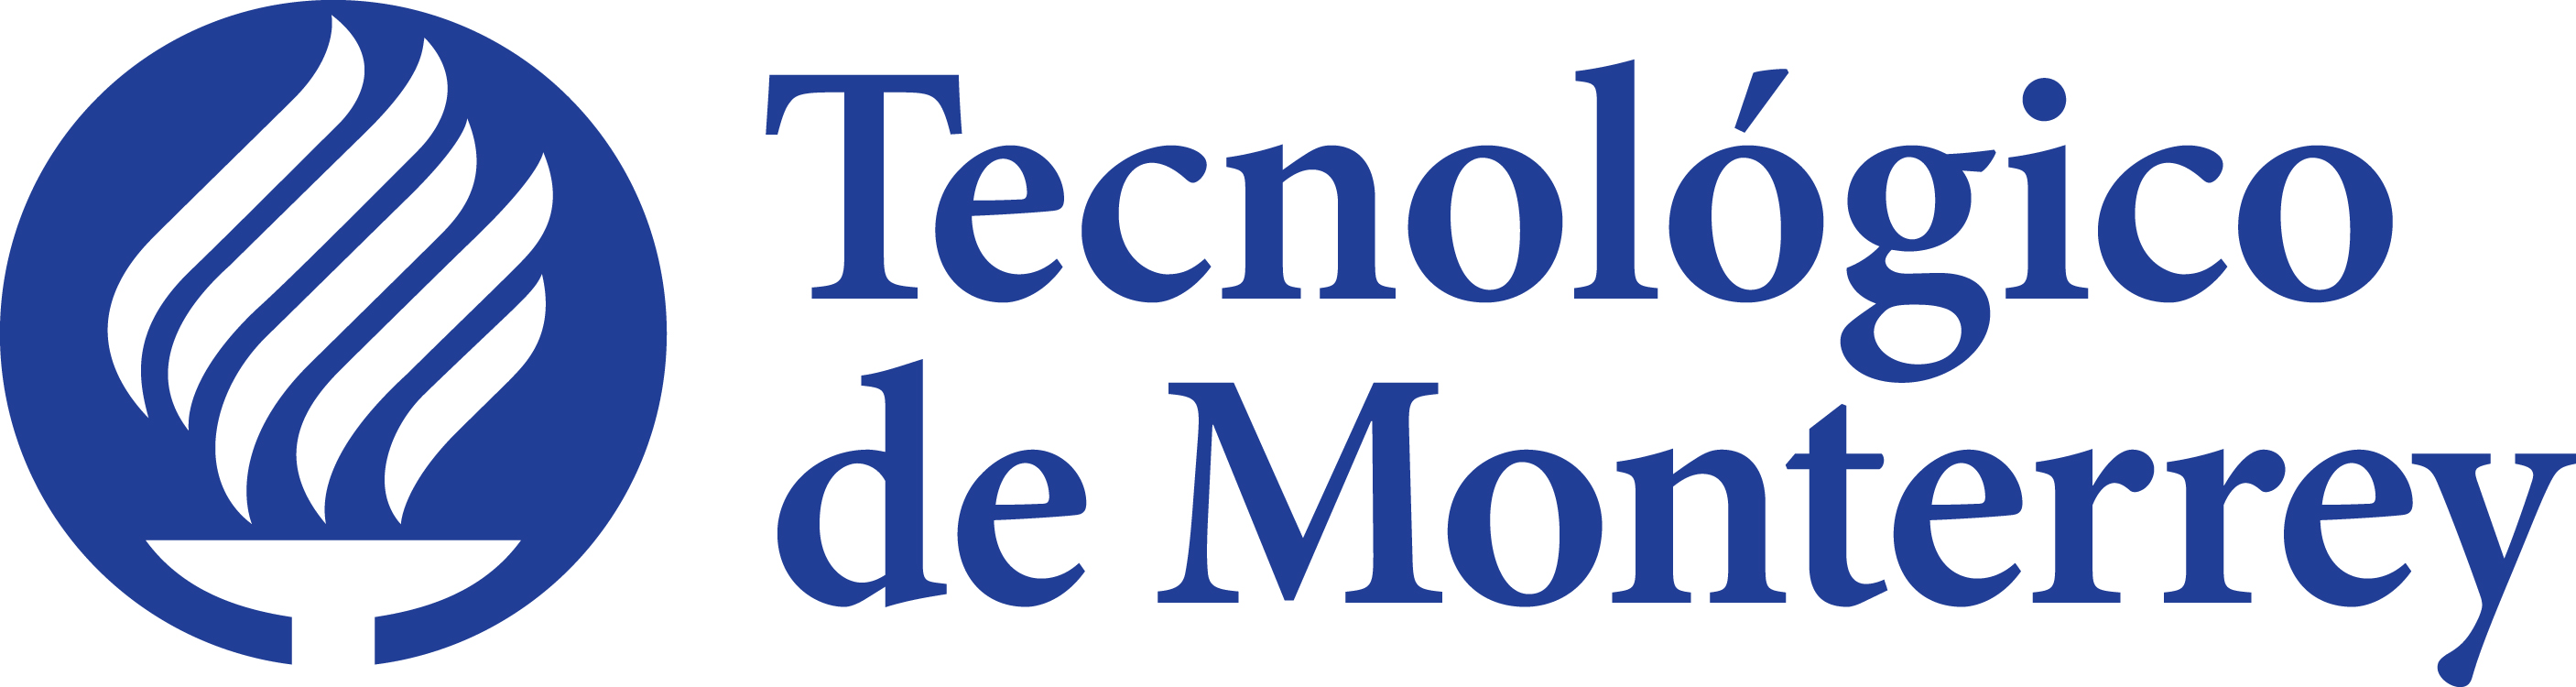

## Modelación computacional aplicando leyes de conservación 

- Alan Corona Lopez A01642342

**Vinculo a carpeta con documento mlx**

**Limpieza de variables**

close all
clearvars
clc

**Circuito inicial**

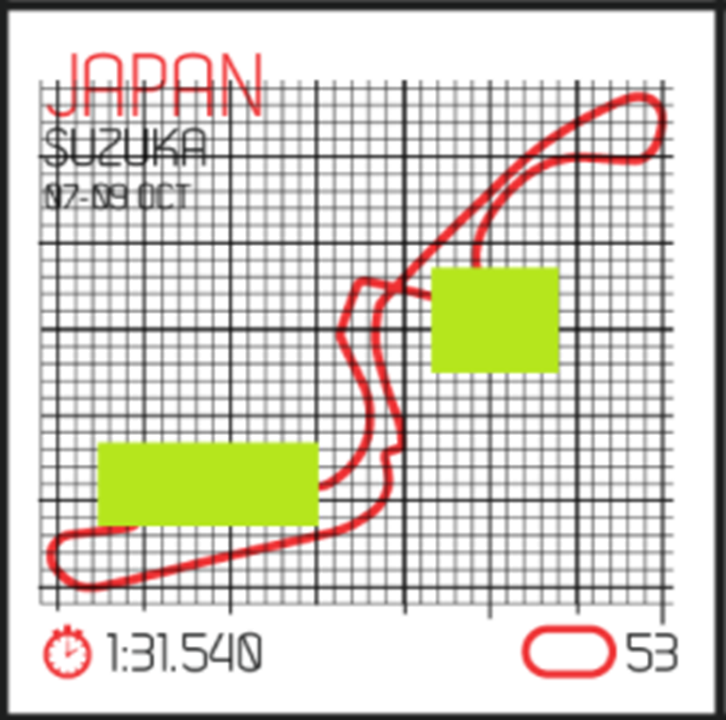

Se plantea el diseño de una pista a apartir de una ecuacion cubica, cuya forma general es:

y = Ax^3 + Bx^2 + Cx + D

En el programa se quiere que la distancia del circuito diseñado sea mayor a 3km pero menor o igual a 5km.

Tambien se calcula la posicion de dos gradas, poniendo en primer lugar la seguridad del espectador. Para esto primeramente se tienen que obtener los rangos donde el radio de curvatura es menor a 100m, ya que en los puntos donde el radio es menor hay altas probabilidades que el auto derrape o se salga de la pista. 

**Datos iniciales**

Se definen las coordenadas iniciales donde se insertara la pista diseñada, con referencia de la imagen anterior


Xinicial = 6;
Yinicial = 6;
Xfinal = 8;
Yfinal = 16;
pasoEvaluacionCurva =11;
coeficienteFriccion = 0.4;
angulo_peralte =19;


Velocidad = 188;

ConvercionKm = @(d)d * 0.1 * 16583 / 39370;
ConvercionEscala = @(d)(d *39370)/(0.1*16583);

aGrada = ConvercionEscala(80/1000); % largo de la grad
bGrada = ConvercionEscala (10/1000); % profundidad de la grada 


**Coeficientes de funcion cubica**

Se definen los coeficientes para llenar la forma general del polinomio cubico. 

Tomo los que mejor ajustaron a los puntos de la rubrica por la limitante de la longitud de curva


% A3 = 11.452;
% A2 = -241.26;
% A1 = 1688;
% A0 = -3911.3; 

% A3 = 10.288;
% A2 = - 217.13;
% A1 = 1521.4 ;
% A0 = - 3526.9; 

A3 = 7.3558;
A2 = -157.43;
A1 = 1119.5;
A0 = -2631.3; 

% A3 = 5.2107;
% A2 = -111.94;
% A1 = 800.03;
% A0 = -1888.9; 


**Paso de funcion y funcion**

En esta seccion se declara la forma de la funcion cubica, la primera y segunda derivada de la misma para poder hacer los calculos requeridos

El paso corresponde a la difeencia de valores en los que grafico la curva


paso = 0.01;
funcion = @(x)(A3*x^3)+(A2*x^2)+(A1*x)+A0;
dfuncion = @(x)(3*A3*x^2)+(2*A2*x)+(A1);
ddfuncion = @(x)(6*A3*x)+(2*A2);


**Coordenadas de funcion**

Se calculan los vectores de valores de la pista (acuacion 3er grado) en "X" y "Y" para su graficacion y su evaluacion 


Xfuncion = [Xinicial];
Yfuncion = [Yinicial];

for i = Xinicial:paso:Xfinal
    Xfuncion(end+1) = i;
    Yfuncion(end+1) = funcion(i);
end

Xfuncion(end+1) = Xfinal;
Yfuncion(end+1) = Yfinal;
plot(Yfinal, Xfinal,'-o',Yinicial,Xinicial,'-o')


**Valores criticos**

Se calcularon los dos puntos criticos de la ecuacion de 3er grado ( la pista ) a partir de la derivada de esta ecuacion.

Evaluando la ecuacion derivada a cero se resuelve la ecuacion de segundo grado a partr de la regla general


[Critico1Y,Critico2Y,Critico1X,Critico2X] = Vcriticos(A3,A2,A1,funcion);


**Grafica de funcion**

Posteriormente, una vez obtenidos los valores de los puntos de la pista y sus puntos criticos se grafican


longitud_funcion = longitud_curva_numerica(Xfuncion,Yfuncion);
xlim([5 17]);
ylim([5 17]);
hold on
plot(Yfuncion,Xfuncion,'LineWidth',0.5,'Color','r')
title('Tramo #1 pista F1')
fprintf(['La pista a escla comineza en el punto (%f, %f) y termina ' ...
    'en (%f, %f)'],Xinicial,Yinicial,Xfinal,Yfinal)

La pista a escla comineza en el punto (6.000000, 6.000000) y termina en (8.000000, 16.000000)

fprintf(['\nLa pista en km comineza en el punto (%f km,%f km) y termina ' ...
    'en (%f km, %f km)\n\n'],ConvercionKm(Xinicial),ConvercionKm(Yinicial), ...
    ConvercionKm(Xfinal),ConvercionKm(Yfinal))


La pista en km comineza en el punto (0.252725 km,0.252725 km) y termina en (0.336967 km, 0.673934 km)



fprintf("\n\tLa pista mide %f kilometros ",ConvercionKm(longitud_funcion))


	La pista mide 0.601556 kilometros 

fprintf(['\tLos puntos criticos a escala son\n\tCritico1: (%f, %f)\n' ...
    '\tCritico2:(%f, %f)'],Critico1X,Critico1Y,Critico2X,Critico2Y)

	Los puntos criticos a escala son
	Critico1: (12.727652, 7.538737)
	Critico2:(14.677665, 6.729369)

fprintf('\n\tLos puntos criticos en km son\n\tCritico1: (%f, %f)\n\tCritico2:(%f, %f)', ...
    ConvercionKm(Critico1X),ConvercionKm(Critico1Y),ConvercionKm(Critico2X), ...
    ConvercionKm(Critico2Y))


	Los puntos criticos en km son
	Critico1: (0.536100, 0.317538)
	Critico2:(0.618237, 0.283447)

hold on
plot(Critico1X, Critico1Y,'-*',Critico2X,Critico2Y,'*')
text(Critico2X,Critico2Y,' <---- Punto Critico')
text(Critico1X,Critico1Y,' <---- Punto Critico')
text(Yfuncion(1),Xfuncion(1),'inicio')
text(Yfuncion(end), Xfuncion(end),'final');

fprintf('La coordenada maxima absoluta (%f, %f)\nLa coordenada del minimo absoluto (%f, %f)', ...
    Xinicial,Yinicial,Xfinal,Yfinal)

La coordenada maxima absoluta (6.000000, 6.000000)
La coordenada del minimo absoluto (8.000000, 16.000000)

fprintf('Los extremos locales son los puntos criticos:\n (%f, %f)\n (%f, %f)', ...
    Critico1X,Critico1Y,Critico2X,Critico2Y)

Los extremos locales son los puntos criticos:
 (12.727652, 7.538737)
 (14.677665, 6.729369)

**Radio de curvatura **

Para poder evaluar en cuales puntos de la pista es probable que un carro derrape y/o se salga de la pista es importante evaluar la zona de derrape a partir de el radio de curvatura de la funcion cubica y graficar las posibles trayectorias que tomaria un coche en caso de salirse de la pista a partir de su segunda derivada  (pendiente tangente) y obtener la recta tangente a dichos puntos


[puntos_peligro_x,puntos_peligro_y,radiosCurva,radiosCurvaMetros] = puntosCurvatura(Xfuncion, ...
    A3,A2,A1,funcion,dfuncion,ConvercionEscala,ConvercionKm,pasoEvaluacionCurva);

Graficar_puntos(puntos_peligro_x,puntos_peligro_y)
Graficar_tangente(funcion,dfuncion,puntos_peligro_x(1),puntos_peligro_x(end),0.05);

fprintf('Las coordenadas de los puntos de derrape son: ')

Las coordenadas de los puntos de derrape son: 

puntos_peligro_x

puntos_peligro_x =     6.2235    6.2412    6.2598    6.2795    6.3003    6.3225    6.3463    6.3721    6.4003    6.4317    6.4673    6.5089    6.5600    6.6288    6.7447    6.9969    7.0748    7.1459    7.2156    7.2880    7.3683    7.4687    7.6407    7.7552    7.8074    7.8478    7.8817    7.9115    7.9382    7.9626    7.9851


puntos_peligro_y

puntos_peligro_y =    11.4394   11.6937   11.9474   12.2004   12.4526   12.7038   12.9539   13.2023   13.4487   13.6923   13.9317   14.1646   14.3856   14.5799   14.6756   14.1793   13.9152   13.6599   13.4120   13.1733   12.9506   12.7689   12.8282   13.2206   13.5149   13.7976   14.0750   14.3492   14.6214   14.8921   15.1616


ix = [puntos_peligro_y(1),puntos_peligro_y(end)];
iy = [puntos_peligro_x(1), puntos_peligro_x(end)];
fprintf("Estos datos estan en los intervalo de la escala: ")

Estos datos estan en los intervalo de la escala: 

ix

ix =    11.4394   15.1616


iy

iy =     6.2235    7.9851


**Posicion de las gradas**

Despues de evaluar las zonas de derrape podemos tomar la decision de donde considero prudente poner gradas donde los espectadores esten lo mas a salvo de un coche

Decidimos poner una grada en el punto de inflexion de la ecuacion, un punto donde me he asegurado que las tangentes los puntos evaluados no impactaran con la grada

La otra grada la asigne en un punto intermedio entre las coordenadas de "X" de el punto critico bajo con el punto en "X" inicial de la zona de darrape

Estas zonas son seguras para el espectador y de gran atraccion por la curva que se tiene que dar 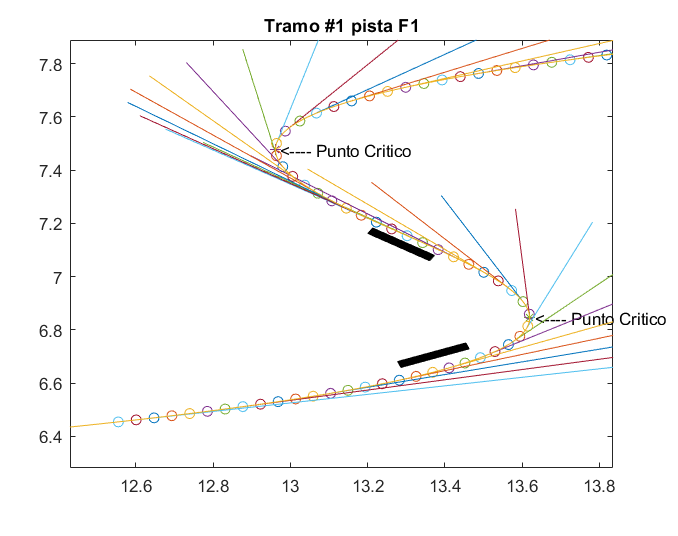

%pGrada1 = puntos_peligro_x(1);
% pGrada1 = ((Critico1Y+puntos_peligro_x(1))/2)-0.5 ; 
% gradas(dfuncion,funcion,pGrada1,aGrada,bGrada,ConvercionEscala);

%ajusteX, ajuste Y, ajuste Angulo
pGrada3 = Critico1Y; 
ajusteXgrada3 = 0.3;
ajusteYgrada3 = 0.1;
ajusteAnguloGrada3 = 10;
gradas(dfuncion,funcion,pGrada3,aGrada,bGrada,ConvercionEscala,ajusteXgrada3, ...
    ajusteYgrada3,ajusteAnguloGrada3);

% pGrada2 = ((Critico2Y+Critico1Y)/2)-0.01;
pGrada2 = puntos_peligro_x(end)+0.01

pGrada2 = 7.9951

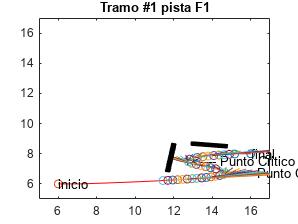

ajusteXgrada2 = 1.5;
ajusteYgrada2 = 0;
ajusteAnguloGrada2 = 10;
gradas(dfuncion,funcion,pGrada2,aGrada,bGrada,ConvercionEscala,ajusteXgrada2, ...
    ajusteYgrada2,ajusteAnguloGrada2);


%pGrada4
pGrada4 = puntos_peligro_x(1)-0.01

pGrada4 = 6.2135

ajusteXgrada4 = 1.5;
ajusteYgrada4 = 0;
ajusteAnguloGrada4 = -10;
%gradas(dfuncion,funcion,pGrada4,aGrada,bGrada,ConvercionEscala,
% ajusteXgrada4,ajusteYgrada4,ajusteAnguloGrada4);


%animacion_carro(Xfuncion,Yfuncion)


En esta parte se logra obtener todas las velocidades de los puntos de la curva donde el radio de curvatura es menor a 100m (donde es posible que se salga de la pista)

%velocidad peralte
funcionVelocidad = Velocidad_maxima(coeficienteFriccion,angulo_peralte);
velocidades = [];
radiosCurva

radiosCurva =    11.9532   11.9532   11.2006   10.4882    9.8141    9.1766    8.5742    8.0051    7.4679    6.9611    6.4833    6.0331    5.6093    5.2104    4.8354    4.4831    4.1523    3.8420    3.5511    3.2786    3.0236    2.7853    2.5626    2.3547    2.1610    1.9805    1.8126    1.6565    1.5116    1.3772    1.2527    1.1376    1.0312    0.9331    0.8427    0.7595    0.6831    0.6130    0.5489    0.4903    0.4368    0.3881    0.3439    0.3038    0.2676    0.2349    0.2054    0.1790    0.1554    0.1343


radiosCurvaMetros

radiosCurvaMetros =   503.4781  503.4781  471.7803  441.7721  413.3789  386.5288  361.1523  337.1828  314.5557  293.2091  273.0834  254.1210  236.2668  219.4674  203.6719  188.8311  174.8977  161.8265  149.5738  138.0979  127.3586  117.3175  107.9377   99.1839   91.0222   83.4202   76.3468   69.7724   63.6687   58.0085   52.7658   47.9161   43.4356   39.3019   35.4935   31.9900   28.7721   25.8211   23.1195   20.6507   18.3987   16.3486   14.4860   12.7976   11.2705    9.8927    8.6528    7.5399    6.5441    5.6558


for i=1:length(radiosCurva)
    rad = ConvercionKm(radiosCurva(i))*1000;
    velocidades(end+1) = ((funcionVelocidad(rad))*3600)/1000;
end

%velocidad sin peralte
funcionVelocidad = Velocidad_maxima(coeficienteFriccion,0);
velocidadesSP = [];
for i=1:length(radiosCurva)
    rad = ConvercionKm(radiosCurva(i))*1000;
    velocidadesSP(end+1) = ((funcionVelocidad(rad))*3600)/1000;
end


velocidades

velocidades =   235.0650  235.0650  227.5451  220.1896  212.9962  205.9627  199.0870  192.3669  185.8003  179.3851  173.1192  167.0006  161.0271  155.1968  149.5076  143.9575  138.5447  133.2670  128.1225  123.1094  118.2257  113.4695  108.8389  104.3322   99.9474   95.6826   91.5363   87.5064   83.5912   79.7891   76.0981   72.5167   69.0431   65.6756   62.4126   59.2523   56.1931   53.2335   50.3718   47.6063   44.9357   42.3582   39.8724   37.4767   35.1698   32.9500   30.8159   28.7662   26.7994   24.9141


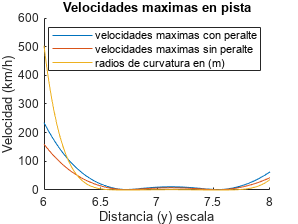

figure(2)
hold on
plot(Xfuncion, velocidades)
plot(Xfuncion, velocidadesSP)
plot(Xfuncion, radiosCurvaMetros)
title('Velocidades maximas en pista')
xlabel('Distancia (y) escala') 
ylabel('Velocidad (km/h)')
legend('velocidades maximas con peralte','velocidades maximas sin peralte', ...
    'radios de curvatura en (m)')

La concatenacion de la pista escalada de la pista de suzuka Japon con la diseñada se veria asi

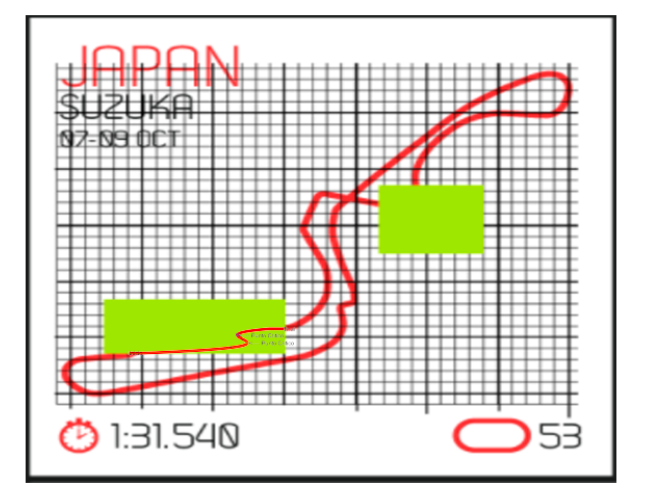

**Animacion con velocidad**

fprintf('menu')

menu

fprintf(['1. Simulación sin accidente\n2.Simulación con derrape en zona de gradas\n3.' ...
    'Simulación con derrape en primera curva\n4.Otra propuesta de gradas'])

1. Simulación sin accidente
2.Simulación con derrape en zona de gradas
3.Simulación con derrape en primera curva
4.Otra propuesta de gradas

op = input("Opcion del menu ---> ")

op = 4

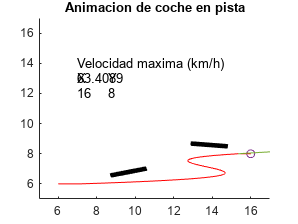

switch op
    case 1
        Velocidad = 1;
        animacionCarro(Xfuncion,Yfuncion,funcion,dfuncion,velocidades,Velocidad,pGrada3, ...
            aGrada,bGrada,ConvercionEscala,ajusteXgrada3,ajusteYgrada3,ajusteAnguloGrada3, ...
            pGrada2,ajusteXgrada2,ajusteYgrada2,ajusteAnguloGrada2,coeficienteFriccion);
    case 2
        Velocidad = 70;
        anticipacion = 0.2
        animacionCarroPunto(Xfuncion,Yfuncion,funcion,dfuncion,velocidades,Velocidad, ...
            pGrada3,aGrada,bGrada,ConvercionEscala,ajusteXgrada3,ajusteYgrada3, ...
            ajusteAnguloGrada3,pGrada2,ajusteXgrada2,ajusteYgrada2,ajusteAnguloGrada2, ...
            coeficienteFriccion,Critico1Y-anticipacion);
    case 3
        Velocidad = 100;
        anticipacion = 0.2
        animacionCarroPunto(Xfuncion,Yfuncion,funcion,dfuncion,velocidades,Velocidad, ...
            pGrada3,aGrada,bGrada,ConvercionEscala,ajusteXgrada3,ajusteYgrada3, ...
            ajusteAnguloGrada3,pGrada2,ajusteXgrada2,ajusteYgrada2,ajusteAnguloGrada2, ...
            coeficienteFriccion,Critico2Y-anticipacion);   
    case 4
        Velocidad = 1;
        animacionCarro(Xfuncion,Yfuncion,funcion,dfuncion,velocidades,Velocidad,pGrada4, ...
            aGrada,bGrada,ConvercionEscala,ajusteXgrada4,ajusteYgrada4,ajusteAnguloGrada4, ...
            pGrada2,ajusteXgrada2,ajusteYgrada2,ajusteAnguloGrada2,coeficienteFriccion);
    otherwise
        fprintf("opcion no reconocida ")
        
end

Funcion distancia numerica

Usé un metodo numerico para poder calcular la longitud de la curva.

A apartir de la iteracion del algoritmo para sacar hipotenusas de pequeños intervalos en "X" y "Y" e irlas sumando en un contador de longitud

function distancia = longitud_curva_numerica(puntosX,puntosY)
    distancia = 0;
    for i=2:length(puntosX)
        puntoAnteriorX = puntosX(i-1);
        puntoAnteriorY = puntosY(i-1);
        puntoActualX = puntosX(i);
        puntoActualY = puntosY(i);
        
        distancia = distancia + sqrt(((puntoActualY - puntoAnteriorY)^2)+((puntoActualX ...
            - puntoAnteriorX)^2));      
    end

end


Funcion puntos criticos

Obtuve las coordenadas de los puntos criticos a partir de la primera derivada de la ecuacion al igualarla a cero, ya que los puntos criticos estan donde la pendiente es cero


function  [vC1Y, vC2Y, vC1X, vC2X] = Vcriticos(a3,a2,a1,func)
    vC1Y = (-(2*a2)+sqrt(((2*a2)^2)-(4*3*a3*a1)))/(2*3*a3);
    vC2Y = (-(2*a2)-sqrt(((2*a2)^2)-(4*3*a3*a1)))/(2*3*a3);
    vC1X = func(vC1Y);
    vC2X = func(vC2Y);
    
end


Funcion generadora de funcion tangente

Partiendo de la ecuacion de la recta y la segunda derivada, pude hacer dos formulas incognitas que podemos llamar para obtener la pendiente tangente y perpendicular a un punto 

Posteriormetene se hizo un modelo que graficara la recta tangente a algun punto de la grafica, con el fin de representar la trayectoria de un coche que se saliera de la pista 


function [Ftangente, FinversaTangente] = recta_pendiente(func,dfunc, punto)
    Ftangente = @(p)((p-punto)*dfunc(punto))+func(punto);
    FinversaTangente = @(p)((p-punto)*(-1/dfunc(punto)))+func(punto);
end

function Graficar_tangente(funcionGrafica,dfuncionGrafica,Lim1rango,Lim2rango,paso_rango)

    for puntoT = Lim1rango: paso_rango: Lim2rango
        funcionTangente = recta_pendiente(funcionGrafica,dfuncionGrafica,puntoT);
        ytan =[];
        xtan = puntoT:0.1:puntoT+0.4;
        for i = puntoT:0.1:puntoT+0.4
            ytan(end+1) = funcionTangente(i);
        end
    
    plot(ytan,xtan)
    end
end



Creacion de gradas

A partir de mis conocimientos de geometria analitica y trigonometria formulé un modelo que graficara y obtuviera la posición de la grada en el punto de la grafica que le diera, obedeciendo a el distanciamiento asignado por seguridad de los espectadores

De la segunda derivada obtuvé la pendiente y angulo de cualquier punto de la funcion para poder asi obtener tambien la pendiente perpendicular y poder sacar los puntos de un rectangulo paralelo a la pendiente del punto de la grafica y que estuviera distanciado perpendicularmete a la tangente de dicho punto

Todo esto repetando ls medidas de las gradas asignadas anteriormente en el inicio del programa


function gradas (funcionPendiente,funcionP, puntoGrada, anchoGradas, largoGradas, ...
    fkm2escala,ajustex,ajustey,ajusteAngulo)

distanciemiento_total = fkm2escala(20/1000);
punto_x = zeros(1,5);
punto_y = zeros(1,5);
pendienteTangente = funcionPendiente(puntoGrada);
pendientePerpendicular = -1/pendienteTangente;
grados_tangente = atan(pendienteTangente)+deg2rad(ajusteAngulo);
grados_perpendicular = atan(pendientePerpendicular)+deg2rad(ajusteAngulo);

grados_distanciamiento = (pi/2)-grados_tangente;

distanciemiento_y = distanciemiento_total*cos(grados_distanciamiento);
distanciemiento_x = distanciemiento_total*sin(grados_distanciamiento);

punto_x(1)=(funcionP(puntoGrada)+(anchoGradas/2)*sin(grados_tangente))-distanciemiento_x-ajustex;
punto_x(2)=(funcionP(puntoGrada)-(anchoGradas/2)*sin(grados_tangente))-distanciemiento_x-ajustex;
punto_x(3)=punto_x(2)+(largoGradas)*sin(grados_perpendicular);
punto_x(4)=punto_x(1)+(largoGradas)*sin(grados_perpendicular);
punto_x(5)=(funcionP(puntoGrada)+(anchoGradas/2)*sin(grados_tangente))-distanciemiento_x-ajustex;

punto_y(1) = (puntoGrada+(anchoGradas/2)*cos(grados_tangente))+distanciemiento_y+ajustey;
punto_y(2) = (puntoGrada-(anchoGradas/2)*cos(grados_tangente))+distanciemiento_y+ajustey;
punto_y(3) = punto_y(2)+(largoGradas)*cos(grados_perpendicular);
punto_y(4) = punto_y(1)+(largoGradas)*cos(grados_perpendicular);
punto_y(5) = (puntoGrada+(anchoGradas/2)*cos(grados_tangente))+distanciemiento_y+ajustey;

hold on
plot(punto_x,punto_y)
fill(punto_x,punto_y,'k')
pgradax = (funcionP(puntoGrada))-distanciemiento_x;
pgraday = (puntoGrada+distanciemiento_y);

end





Funcion del radio de curvatura

La formulacion del modelo para obtener la graficacion de los puntos de derrape se hizo a partir de la formula de radio de curvatura. Para nosotros poder tomar todos los puntos donde era probable que el carro derrapara comparamos que el radio fuera menor a 100 m (a escala que nos asignaron). 

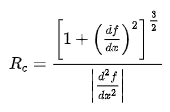

La formula sale a partir de la segunda y tercera derivada de la funcion evaluada

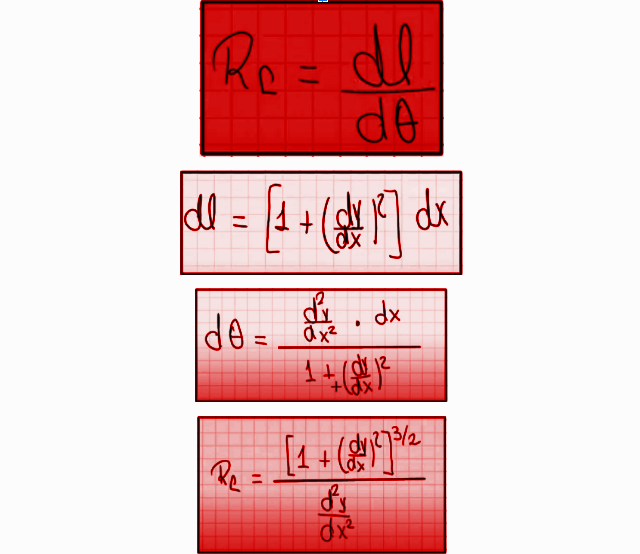

Finalmente, para obtener los puntos con separacion de los metros que nos piden nuevamente hacemos un algoritmo donde usé pitagoras para obtener lahipotenusa constante, ya que a lo largo de toda la trayectoria las x , y cambian


% function [VXCircunferencia,VYCircunferencia]= puntosCurvatura(lim_X,a3,a2,a1,
% func,fkm2escala)
% p = fkm2escala(20/1000);    
% VXCircunferencia = [];    
% VYCircunferencia = []; 
%     for i = lim_X(1):p:lim_X(end)
%         radio = radioCurvatura(a3,a2,a1,i);
%         if radio < fkm2escala(100/1000)
%             VXCircunferencia(end+1) = i;
%             VYCircunferencia(end+1) = func(i);
%         end
%     end     
% end

function [VXCircunferencia,VYCircunferencia,RadioCurvatura,RadioCurvaturaM] = puntosCurvatura( ...
    lim_X,a3,a2,a1,func,dfunc,fkm2escala,fescala2km, p)
p = fkm2escala(p/1000);
RadioCurvatura = [];
RadioCurvaturaM = [];

VXCircunferencia = [];    
VYCircunferencia = [];
i= lim_X(1);
    while i < lim_X(end)
        radio = radioCurvatura(a3,a2,a1,i);
        if radio < fkm2escala(100/1000)
            VXCircunferencia(end+1) = i;
            VYCircunferencia(end+1) = func(i);
        end
        i = i + p*cos(atan(dfunc(i)));
    end
    
    for i = 1: length(lim_X)
        radio = radioCurvatura(a3,a2,a1,lim_X(i));
        RadioCurvatura(end+1) = radio;
        RadioCurvaturaM(end+1) = fescala2km(radio)*1000;
    end
    
end


function Rcurva = radioCurvatura (a3,a2,a1,pCurva)
    Rcurva = ((1+((3*a3*(pCurva^2))+(2*a2*pCurva)+a1)^2)^(3/2))/((6*a3*(pCurva^2))+(2*a2)); 
end

function Graficar_puntos(vecX, vecY)
    for i=1:length(vecX)
        plot(vecY(i),vecX(i),'-o')
    end
end



Funcion de movimiento en una curva con peralte

Se genero una funcion que calcule la velocidad maxima que ouede tomar un auto en una curva a partir del analisis de fuerzas en un peralte y usando la fuerza centripeta


function [Velocidad]=Velocidad_maxima(mu,angulo_peralte)
    gravedad = 9.81;
    Velocidad = @(r)(sqrt(gravedad*r*((mu*cosd(angulo_peralte)+sind(angulo_peralte))/ ...
        (cosd(angulo_peralte)-(mu*sind(angulo_peralte))))));    
    
end


Funcion animacion

se obtienen la animacion a partir de las comparaciones de las velocidades maximas y una velocidad hipotetica de un auto que no respete los limites de velocidad

El calculo de la distancia recorrida desde el punto de derrape se obtiene a partir de la conservacion de la energia igualando la energia cinetica con la que comienza con la energia convertida en friccion 

function animacionCarro(trayectoriaX,trayectoriaY,func,dfunc,velocidades_max,velocidad_carro, ...
    pGrada3,aGrada,bGrada,ConvercionEscala,ajusteX1,ajusteY1,ajuste_angulo1,pGrada2,ajusteX2, ...
    ajusteY2,ajuste_angulo2,cFriccion)
    figure(3)

    for i = 1: length(trayectoriaX)
        clf
        xlim([5 17]);
        ylim([5 17]);
        hold on
        gradas(dfunc,func,pGrada3,aGrada,bGrada,ConvercionEscala,ajusteX1,ajusteY1, ...
            ajuste_angulo1);
        gradas(dfunc,func,pGrada2,aGrada,bGrada,ConvercionEscala,ajusteX2,ajusteY2, ...
            ajuste_angulo2);
        plot(trayectoriaY,trayectoriaX,'LineWidth',0.5,'Color','r')
        title('Animacion de coche en pista')
        txtX = {'X ',trayectoriaY(i)};
        txtY = {'Y ',trayectoriaX(i)};
        txtVel = {'Velocidad maxima (km/h) ',velocidades_max(i)};
        text(8.6,12.5,txtY)
        text(7,12.5,txtX)
        text(7,13.5,txtVel)
        plot(trayectoriaY(i),trayectoriaX(i),'-o')
        Graficar_tangente(func,dfunc,trayectoriaX(i),trayectoriaX(i),0.05)
        if velocidad_carro > velocidades_max(i)
            %colicion
            
            pendienteTangente = dfunc(trayectoriaX(i));
            distFmetros = ((velocidades_max(i)*1000/3600)^2)/(cFriccion*9.81*2);
            distF = ConvercionEscala(distFmetros/1000);
            angulo = atan(pendienteTangente);
            distX = distF*cos(angulo);
            distY = distF*sin(angulo);
            pasoAnimacion = sqrt((trayectoriaY(i)-trayectoriaY(i-1))^2);

            txtfuera = {'Distancia ',distFmetros};
            text(7,11,txtfuera)
            
            Graficar_tangente_simulacion(func,dfunc,trayectoriaX(i),distX, ...
                distY,pasoAnimacion)
            break
        end
        
        pause(0.01)
        
        
    end
end



function animacionCarroPunto(trayectoriaX,trayectoriaY,func,dfunc, ...
    velocidades_max,velocidad_carro,pGrada3,aGrada,bGrada,ConvercionEscala,ajusteX1, ...
    ajusteY1,ajuste_angulo1,pGrada2,ajusteX2,ajusteY2,ajuste_angulo2,cFriccion,puntoX)
    tiempo = 0;
    figure(3)
    for i = 1: length(trayectoriaX)
        clf
        xlim([5 17]);
        ylim([5 17]);
        hold on
        gradas(dfunc,func,pGrada3,aGrada,bGrada,ConvercionEscala,ajusteX1,ajusteY1, ...
            ajuste_angulo1);
        gradas(dfunc,func,pGrada2,aGrada,bGrada,ConvercionEscala,ajusteX2,ajusteY2, ...
            ajuste_angulo2);
        plot(trayectoriaY,trayectoriaX,'LineWidth',0.5,'Color','r')
        tiempo = tiempo + 1; 
        title('Animacion de coche en pista')
        txtX = {'X ',trayectoriaY(i)};
        txtY = {'Y ',trayectoriaX(i)};
        txtVel = {'Velocidad maxima (km/h) ',velocidades_max(i)};
        txtVelDerrape = {'Velocidad en punto de derrape (km/h) ',velocidad_carro};
        txtTiempo = {'Tiempo ',tiempo};
        text(8.6,12.5,txtY)
        text(7,12.5,txtX)
        text(7,13.5,txtVel)
        text(7,10,txtTiempo)
        plot(trayectoriaY(i),trayectoriaX(i),'-o')
        Graficar_tangente(func,dfunc,trayectoriaX(i),trayectoriaX(i),0.05)
        if puntoX == trayectoriaX(i) || trayectoriaX(i) > puntoX 
            if velocidad_carro > velocidades_max(i)
                %colicion
                pendienteTangente = dfunc(trayectoriaX(i));
                distFmetros = ((velocidad_carro*1000/3600)^2)/(cFriccion*9.81*2);
                distF = ConvercionEscala(distFmetros/1000);
                angulo = atan(pendienteTangente);
                distX = distF*cos(angulo);
                distY = distF*sin(angulo);
                pasoAnimacion = sqrt((trayectoriaY(i)-trayectoriaY(i-1))^2);
                aceleracion = -((velocidad_carro*1000/3600)^2)/(2*distFmetros);
                txtVelAccidente = {'Se ha ocacionado un accidente '};
                text(7,15,txtVelDerrape)
                txtfuera = {'Distancia (m) ',distFmetros};
                txtAceleracion = {'aceleracion (m/s2)',aceleracion};
                text(7,11,txtfuera)
                text(10,12.5,txtVelAccidente,'FontSize',15,'Color','r')
                text(11,11,txtAceleracion)
                Graficar_tangente_simulacion(func,dfunc,trayectoriaX(i),distX, ...
                    distY,pasoAnimacion)
                break
            end
        end
        
        pause(0.01)
        
        
    end
end

    
function Graficar_tangente_simulacion(funcionGrafica,dfuncionGrafica,puntoT,desplazamientoX, ...
    ~,paso_rango)
     
        funcionTangente = recta_pendiente(funcionGrafica,dfuncionGrafica,puntoT);
        ytan =[];
        xtan = puntoT:paso_rango:puntoT+desplazamientoX;
        for i = puntoT:paso_rango:puntoT+desplazamientoX
            ytan(end+1) = funcionTangente(i);
        end
    
    comet(ytan,xtan)
end

